# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.4 四维绘图

#### 2.4.1 slice切片显示

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

利用 Matlab 不显示 NaN 的特性；

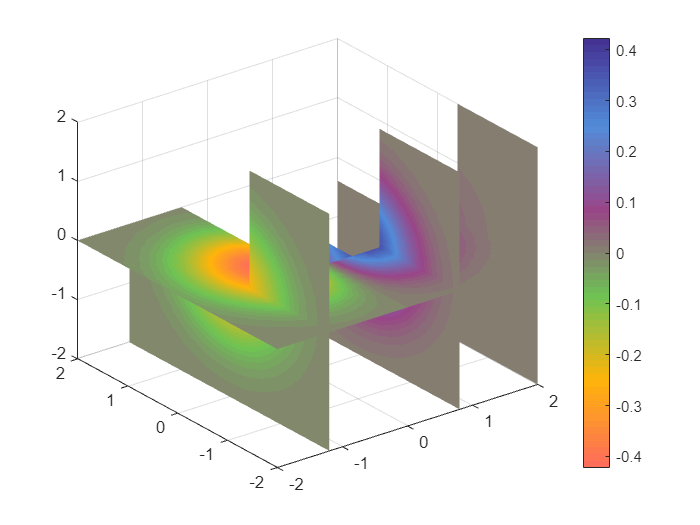

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 创建 colormap
map = GenColormap(all_themes{1});
[X, Y, Z] = meshgrid(-2:0.2:2);
V = X .* exp(-X.^2 - Y.^2 - Z.^2);
% 切片位置
xslice = [-1.2, 0.8, 2];   
yslice = [];
zslice = 0;
s = slice(X, Y, Z, V, xslice, yslice, zslice);
% 裁剪
for i = 1:length(s)
    s(i).XData(10:end, 10:end) = nan;
    s(i).YData(10:end, 10:end) = nan;
    s(i).ZData(10:end, 10:end) = nan;
end
% 加 colorbar 方便看值
colorbar
colormap(map)
shading interp